# Моделирование случайного процесса

# (Аддитивный белый гауссовский шум).

## Прохождение сигнал+шум через фильтр.

Константы используемые в дальнейшей работе

fd=1000; % частота дискретизации
t=0:1/fd:1; % временные отсчёты
fs=20; % частота сигнала
snr=10; % отношение сигнал/шум

Определяем сигнал

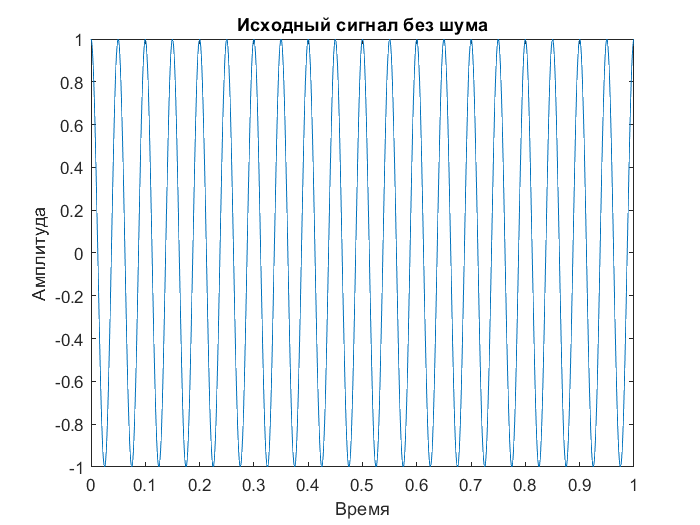

x=cos(2*pi*fs*t);

plot(t, x);
title("Исходный сигнал без шума");
xlabel("Время");
ylabel("Амплитуда");

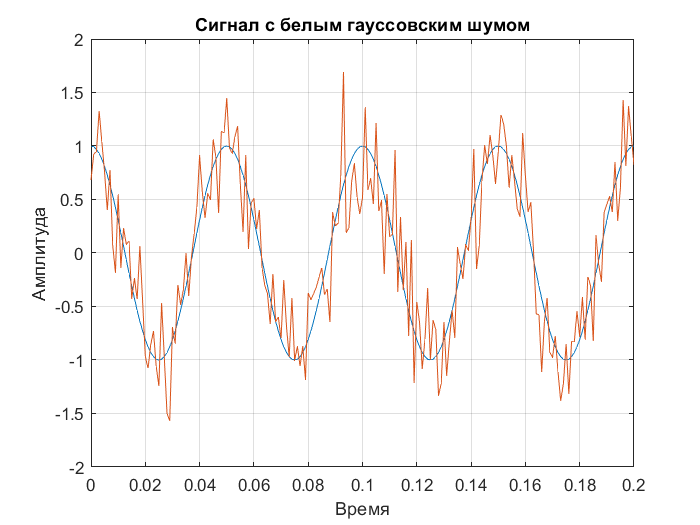


x_shum=awgn(x, snr);

plot(t, x);
xlim([0 0.2]);
ylim([-2 2]);
grid on;
hold on;
plot(t, x_shum);
title("Сигнал с белым гауссовским шумом");
xlabel("Время");
ylabel("Амплитуда");
hold off;

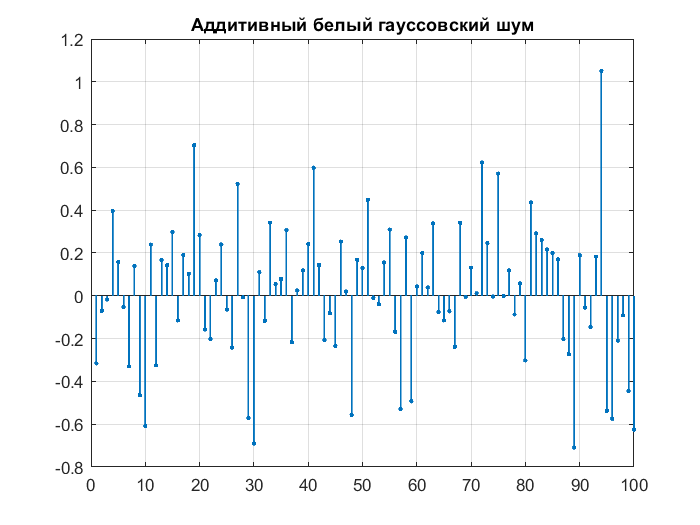


noise=x_shum-x;
stem(noise, 'LineWidth', 1, 'Marker', '.');
title("Аддитивный белый гауссовский шум");
grid on;
xlim([0 100]);

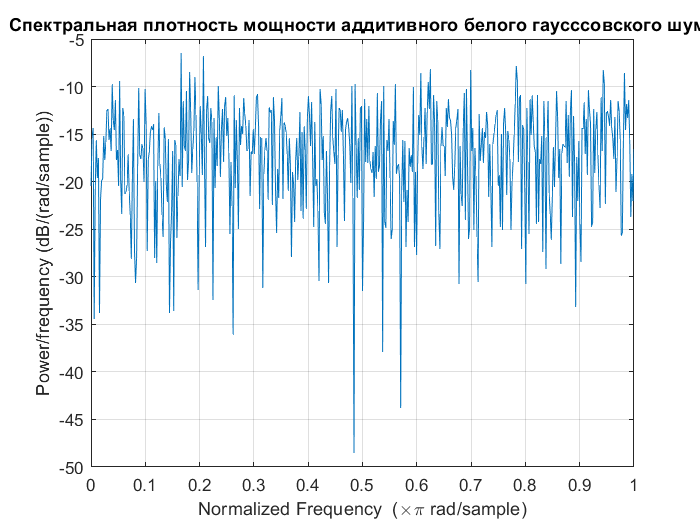


periodogram(noise);
grid on;
title("Спектральная плотность мощности аддитивного белого гаусссовского шума");

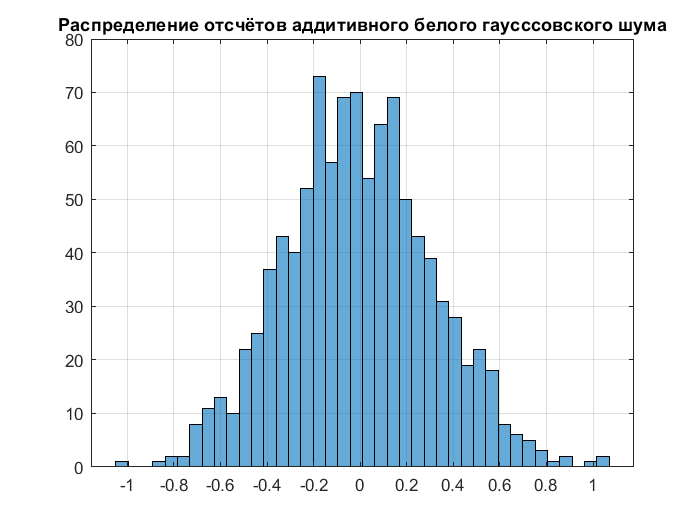


histogram(noise, 40);
grid on;
title("Распределение отсчётов аддитивного белого гаусссовского шума");

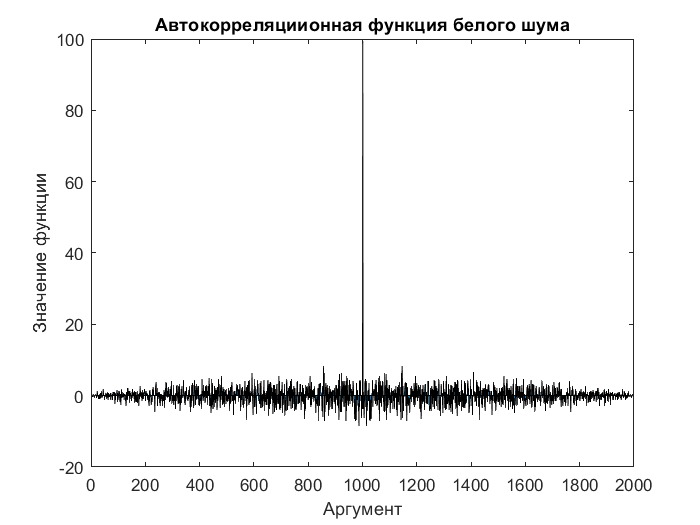


area(xcorr(detrend(noise)))
xlim([0 2000])
title("Автокорреляциионная функция белого шума");
xlabel("Аргумент");
ylabel("Значение функции"); 

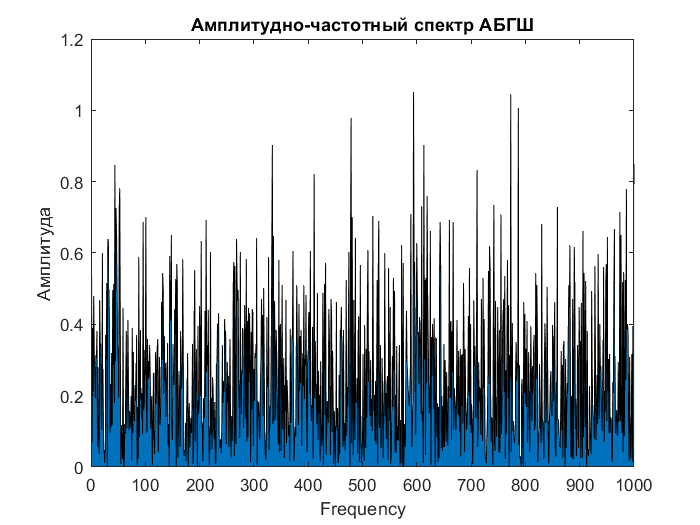


S_shum=fftshift(noise);

area(abs(S_shum));
title("Амплитудно-частотный спектр АБГШ");
xlabel("Frequency");
ylabel("Амплитуда");
xlim([0 1000]);

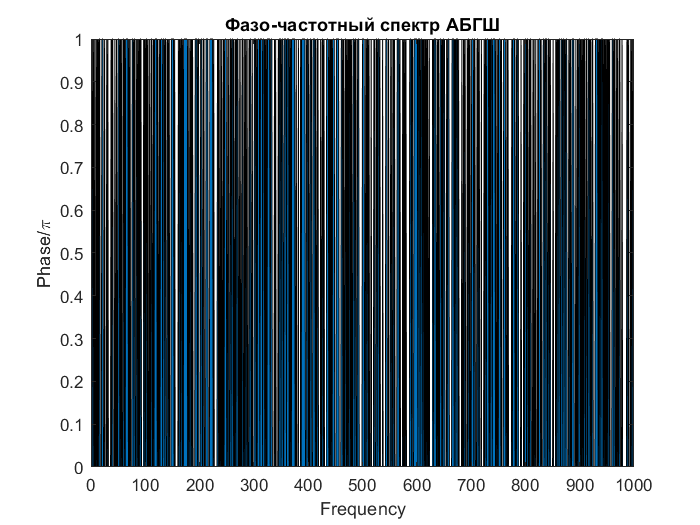


area(angle(S_shum)/pi);
title("Фазо-частотный спектр АБГШ");
xlabel("Frequency");
ylabel("Phase/\pi");
xlim([0 1000]);

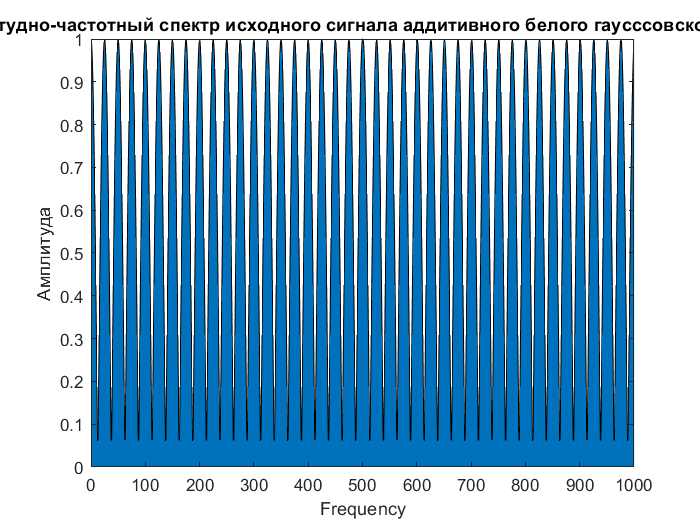


S_x=fftshift(x);

area(abs(S_x));
xlim([0 1000]);
title("Амлитудно-частотный спектр исходного сигнала аддитивного белого гаусссовского шума");
xlabel("Frequency");
ylabel("Амплитуда");

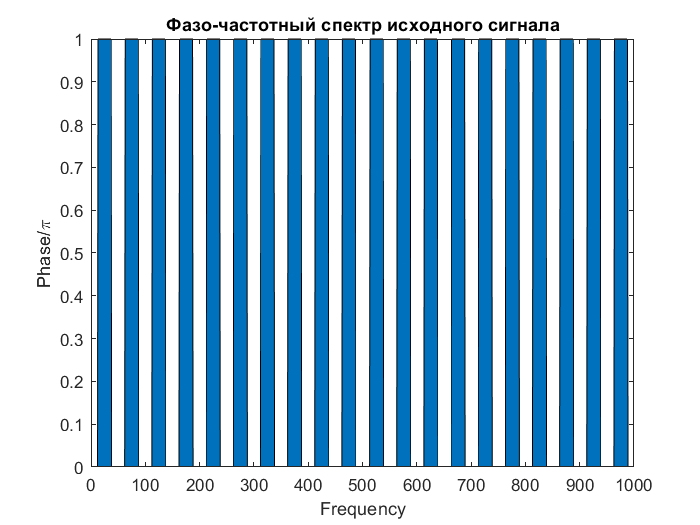


area(angle(S_x)/pi);
xlim([0 1000]);
title("Фазо-частотный спектр исходного сигнала");
xlabel("Frequency");
ylabel("Phase/\pi");

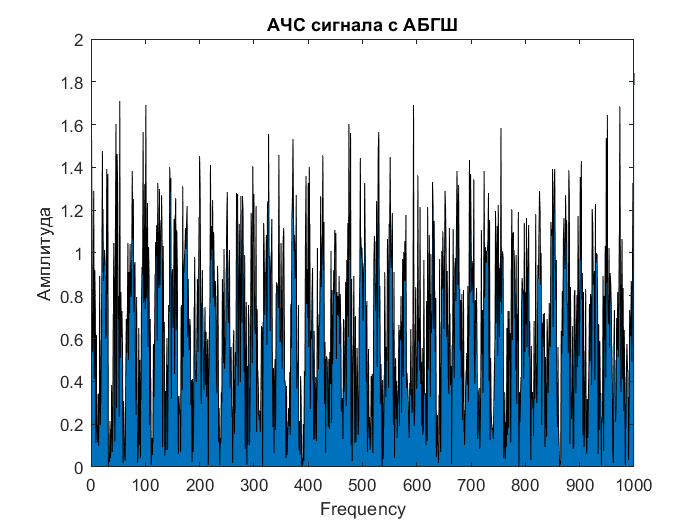


S_shum_x=fftshift(x_shum);

area(abs(S_shum_x));
xlim([0 1000]);
xlabel("Frequency");
ylabel("Амплитуда");
title("АЧС сигнала с АБГШ");

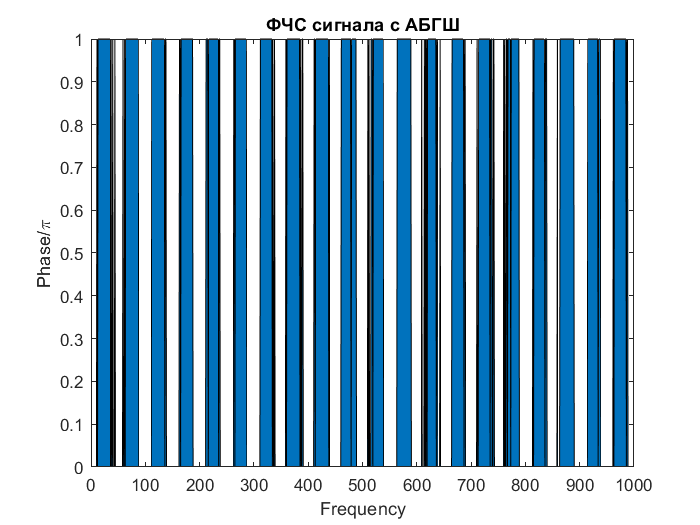


area(angle(S_shum_x)/pi);
xlim([0 1000]);
xlabel("Frequency");
ylabel("Phase/\pi");
title("ФЧС сигнала с АБГШ");

# Сглаживающее среднее как цифровой фильтр.

Суммируем зашумленную синусоиду и чистую:

s_aver=x+x_shum;

Импульсная характеристика:

num=10;
h=ones(1, num)./num;

Построим усреднённую синусоиду, чистую и зашумленную:

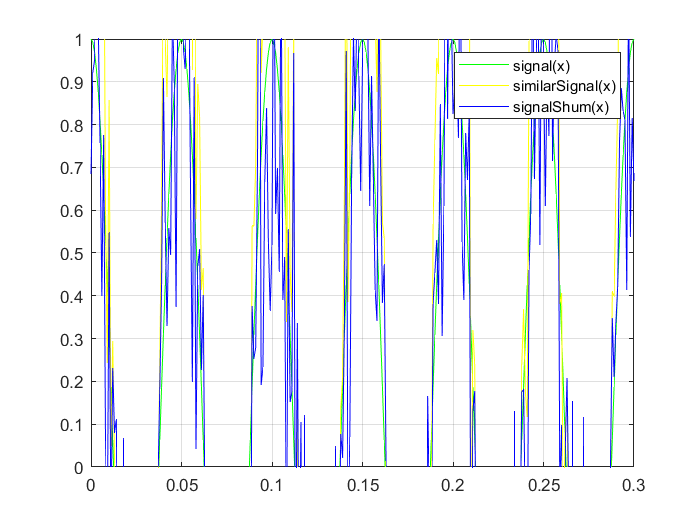

plot(t, x, 'Color', 'green');
xlim([0 0.3]);
ylim([0 1]);
hold on;
grid on;
plot(t, s_aver, 'Color', 'yellow');
xlim([0 0.3]);
ylim([0 1]);
hold on;
grid on;
plot(t, x_shum, 'Color', 'blue');
xlim([0 0.3]);
ylim([0 1]);
hold on;
grid on;
legend('signal(x)', 'similarSignal(x)', 'signalShum(x)');
hold off;

## Cвёртка сигнала с импульсной характеристикой:

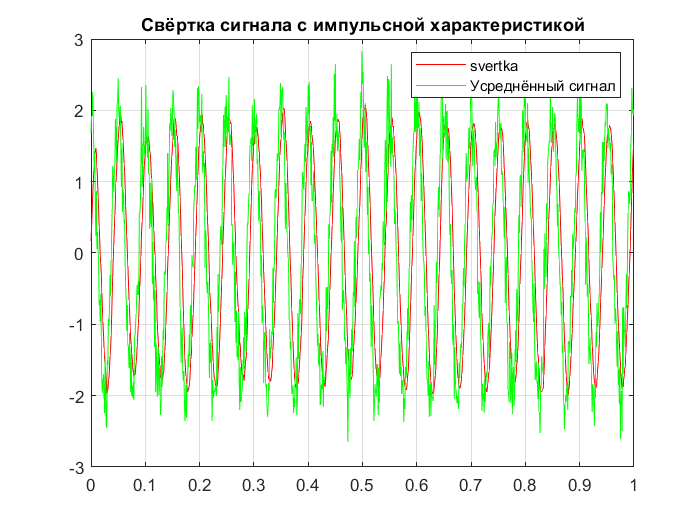

svertka=conv(s_aver, h);
plot(t, svertka(1:length(t)), 'Color', 'red');
title("Cвёртка сигнала с импульсной характеристикой")
hold on;
grid on;
plot(t, s_aver, 'Color', 'green');
hold on;
grid on;
legend("svertka", "Усреднённый сигнал");
hold off;

## Оценка АЧХ и ФЧХ фильтра:

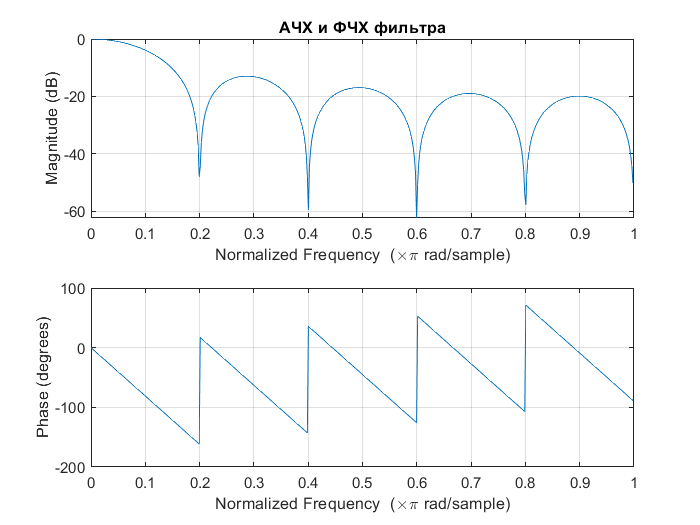

freqz(h,1);
title("АЧХ и ФЧХ фильтра");